# Cvičení 8 - B2M31AEDA

## Nahrání dat

**Popis dat:** Pracovní data jsou uložena v souboru data.csv, který je k dispozici ke stažení na Moodle stránce tohoto předmětu, ve složce příslušného cvičení. Pro načtení dat do Matlabu využijte funkce `readtable`*.*

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week08' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
T = readtable('data.csv','ReadVariableNames',true);
sampleSize = height(T);
parameters = ["jitter", "DDKR", "VOT", "stdPWR", "stdF0", "PPT", "AmpDec", "VFT", ...
    "UPDRS_III_bradykinesia", "UPDRS_III_axial", "UPDRS_III", "L_dopa_equivalent"];
Nparameters = length(parameters);
alpha = 0.05;

## 1. Vyhledání lineárních vztahů mezi parametry

- Pomocí korelační analýzy najděte mezi možnými dvojicemi nezávislých parametrů takové, které budou vykazovat významný lineární vztah.

- Nezávislá dvojice například **není** celkové skóre dotazníku UPDRS a skóre z nějaké z jeho podsekcí.

- Hranici pro určení toho, který vztah je významný, a který ne, určete buď na základě vámi zvolené hraniční hodnoty korelačního koeficientu nebo pomocí statistické významnosti korelace vůči vybrané úrovni alfa.

**Uveďte, jak jste nastavili hranici významnosti a korektně reportujte výsledky korelační analýzy pro nejvýznamnější dvojice.**

normality = reportNormality(T, parameters, alpha);

	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample jitter (M = 1.20, SD = 0.96)
at significance level α = 0.05, W(16) = 0.8278, p = 0.007.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample DDKR (M = 6.44, SD = 0.90)
at significance level α = 0.05, W(16) = 0.9686, p = 0.79.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample VOT (M = 24.31, SD = 6.03)
at significance level α = 0.05, W(16) = 0.9388, p = 0.26.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample stdPWR (M = 6.97, SD = 0.85)
at significance level α = 0.05, W(16) = 0.9600, p = 0.63.

	Shapiro-Wilk test confirms that the null hy

reportCorrelation(T, parameters, normality, alpha)

A Pearson correlation test was conducted to assess the relationship between two parameters:
	VOT (M=24.315, SD=6.028),
	PPT (M=11.015, SD=2.277).
Considering the level of significance α = 0.05, there was a significant relationship between
these parameters, r(15) = -0.597, p = 0.01.

A Pearson correlation test was conducted to assess the relationship between two parameters:
	VOT (M=24.315, SD=6.028),
	VFT (M=1.397, SD=0.527).
Considering the level of significance α = 0.05, there was a significant relationship between
these parameters, r(15) = 0.634, p = 0.006.

A Pearson correlation test was conducted to assess the relationship between two parameters:
	PPT (M=11.015, SD=2.277),
	VFT (M=1.397, SD=0.527).
Considering the level of significance α = 0.05, there was a significant relationship between
these parameters, r(15) = -0.658, p = 0.004.

A Pearson correlation test was conducted to assess the relationship between two parameters:
	PPT (M=11.015, SD=2.277),
	UPDRS_III_bradykinesia (M=6.1

#### Vaše odpovědi a výsledky:

- Ani v jednom z provedených testů nebyla aplikována Bonferroniho korekce hladiny statistické významnosti pro minimalizaci chyby I. typu pro přílišnou přísnost pro větší množství testů.

- Před provedením korelační analýzy jsme data vyšetřili pro normalitu, abychom tak mohli rozhodnout o typu korelačního testu - Pearsonův pro parametrická a Spearmanův pro neparametrická data.

- K určení významnosti (lineárního) vztahu mezi měřenými veličinami jsme využili hodnoty statistické významnosti $p$ výsledné pro daný test korelace.

- Pro další práci s vybranou dvojící byla zvolena dvojice *PPT/VFT *na základě silné korelace a parametričnosti.

## 2. Regrese

- Vyberte **jednu libovolnou významnou dvojici** a vizualizujte jí ve 2D.

- Vytvořte lineární regresní model pro vybraná data. Parametry modelu (tj. v tomto případě směrnici a posun přímky) vypočítejte pomocí vztahu:

                                                          

- Váš výpočet srovnejte s výstupem funkce `fit` nebo `polyfit.`

- Pomocí vypočtených regresních parametrů si vykreslete lineární regresní přímku do obrázku s vizualizovanými daty.

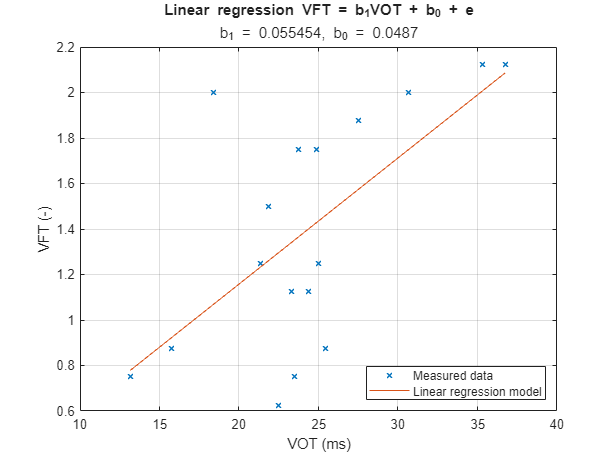

xParameter = "VOT";
xUnits = "ms";
yParameter = "VFT";
yUnits = "-";

y = T.(yParameter);
x = T.(xParameter);
X = [ones(sampleSize, 1), x];
b_LR = ((X.'*X)\X.')*y;
LRmodel = X*b_LR;

figure(1)
plot(x, y, 'x', 'MarkerSize', 5, 'LineWidth', 1)
hold on
plot(x, LRmodel)
hold off
grid on
xlabel(sprintf('%s (%s)', xParameter, xUnits))
ylabel(sprintf('%s (%s)', yParameter, yUnits))
legend('Measured data', 'Linear regression model', 'Location', 'southeast')
title(sprintf('Linear regression %s = b_{1}%s + b_0 + e', yParameter, xParameter))
subtitle(['b_1 = ', num2str(b_LR(2)), ', b_0 = ' num2str(b_LR(1))])

#### Vaše odpovědi a výsledky:

assert(all(round(b_LR, 4) == round(flipud(polyfit(x, y, 1).'), 4)))

Manuální výpočet koeficientů lineárně regresního modelu sedí na výstup funkce *polyfit*.

## 3. Robustní regresní model

Naprogramujte výpočet robustního lineárního **model pomocí *****Theil-Senovy***** metody:**

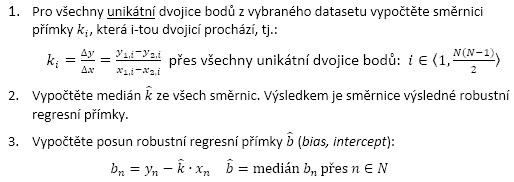

Pomocí vypočtených parametrů **vykreslete robustní lineární regresní přímku** do stejného obrázku jako v přechozím bodě. Odpovídá výsledek očekávání?

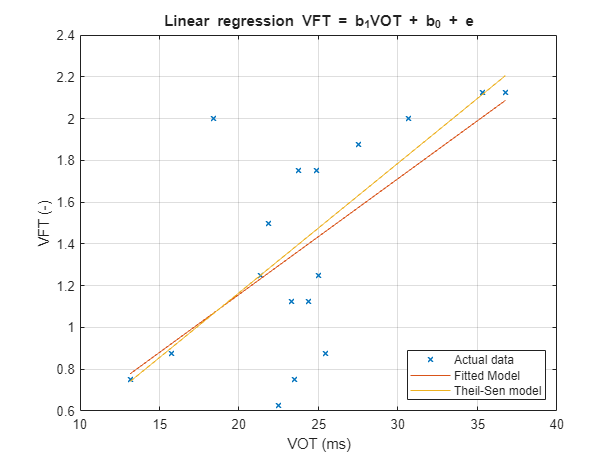

% k_i
[delta_y, delta_x] = deal(nan(sampleSize, sampleSize));
for l = 1:sampleSize
    for n = 1:sampleSize
        delta_y(l,n) = y(l) - y(n);
        delta_x(l,n) = x(l) - x(n);
    end
end
delta_y = tril(delta_y, -1);
delta_x = tril(delta_x, -1);
k = delta_y./delta_x;
k = k(~isnan(k));
k = k(k ~= 0);
% \hat{k}
b_TS(2) = median(k);
% \hat{b}
b_TS(1) = median(y - b_TS(2)*x);

b_TS = b_TS.';
TSmodel = X*b_TS;

figure(2)
plot(x, y, 'x', 'MarkerSize', 5, 'LineWidth', 1)
hold on;
plot(x, LRmodel);
plot(x, TSmodel);
hold off
grid on
xlabel(sprintf('%s (%s)', xParameter, xUnits))
ylabel(sprintf('%s (%s)', yParameter, yUnits))
legend('Actual data','Fitted Model','Theil-Sen model', 'Location', 'southeast')
title(sprintf('Linear regression %s = b_{1}%s + b_0 + e', yParameter, xParameter))

#### Vaše odpovědi a výsledky:

Výsledky odpovídají očekáváním, kdy Theil-Senova metoda představuje robustenější variantu modelu lineární regrese, neboť je založena na mediánu naměřených dat.

## 3. Vyhodnocení kvality modelů

**Analyzujte, jak dobře vámi vytvořené lineární modely popisují výchozí data. Pro oba vaše modely (klasický lineární a robustní Theil-Senův) manuálně vypočtěte následující „*****goodness-of-fit*****“ (GOF) veličiny:**

- Dvouvzorkový **Kolmogorov-Smirnov test** (`kstest2`): zapište hypotézy, které bude test ověřovat, výsledek korektně reportujte.

- **SSE** (*Sum squared error*)

- **RMSE** (*Root mean squared error*)

- Koeficient determinace **R****2**

- **Adjusted**** R****2 **

Ve vzorcích výše je *n* je množství dat, na kterých je model založen (délka *y*) a *m* je počet parametrů, které jsou použity pro výpočet modelu (řád modelu).

Nakonec vytvořte pomocí funkce `fitlm` **vícedimenzionální lineární regresní model**, který bude mít stejnou výstupní proměnnou *y *a pro výpočet modelu použije všechny dostupné nezávislé parametry z tabulky. Nechte si vypsat výstup funkce `fitlm`, který obsahuje automaticky vypočtené *GOF* veličiny.

- Porovnejte výsledky GOF klasického a robustního modelu. Vysvětlete rozdíly mezi nimi.

- Vysvětlete rozdíly v GOF mezi modelem založeným na jednom parametru a vícedimenzionálním modelem. Jaké jsou výhody a nevýhody obou modelů?

X = nan(sampleSize, Nparameters);
for i = 1:Nparameters
    X(:, i) = T.(parameters(i));
end
X(:, parameters==yParameter) =[];
MDLRmodel = fitlm(X, y, 'linear')

MDLRmodel = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11

Estimated Coefficients:
                    Estimate        SE         tStat       pValue 
                   __________    _________    ________    ________

    (Intercept)       -3.1769       1.9542     -1.6257     0.16495
    x1                0.56495      0.23295      2.4252     0.05973
    x2                0.43588      0.16769      2.5992    0.048293
    x3               0.046419     0.026011      1.7846      0.1344
    x4                0.10036      0.17684     0.56754     0.59488
    x5               -0.21257       0.2895    -0.73426     0.49576
    x6              -0.039702     0.077677    -0.51111     0.63104
    

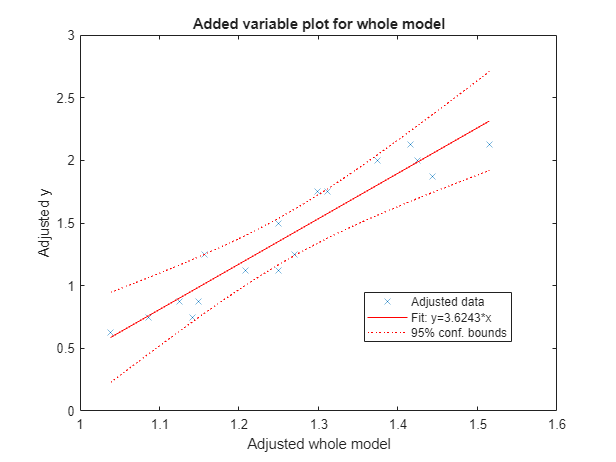

figure(3)
plot(MDLRmodel)

model = [LRmodel TSmodel MDLRmodel.Fitted];
model_type = ["least squares" "Theil-Sen" "multi-dimensional"];
model_order = [1 1 11];

[h, p, ks2stat, SSE, RMSE, R2, Radj] = deal(nan(1,3));
for i = 1:3
    [~, p(i), ks2stat(i)] = kstest2(y,model(:,i),'Alpha',0.05);
    assert(p(i) > alpha)
    fprintf("Kolmogorov-Smirnov test results for\n" + ...
        "\toriginal data (M = %.2f, SD = %.2f),\n" + ...
        "\t%s linear regression model (M = %.2f, SD = %.2f),\n" + ...
        "D(%d) = %.4f, p = %.2f.\n" + ...
        "Null hypothesis is confirmed at a significance level α = %.2f.\n\n", ...
        mean(y), std(y), model_type(i), mean(model(:, i)), std(model(:, i)), sampleSize, ks2stat(i), p(i), alpha);
    SSE(i) = sum((y - model(:,i)).^2);
    RMSE(i) = sqrt(SSE(i)/(sampleSize - model_order(i) - 1));
    R2(i) = 1 - ((sum((y - model(:,i)).^2))/(sum((y - mean(y)).^2)));
    Radj(i) = 1 - ((1 - R2(i))*(sampleSize - 1)/(sampleSize - model_order(i) - 1 ));
end

Kolmogorov-Smirnov test results for
	original data (M = 1.40, SD = 0.53),
	least squares linear regression model (M = 1.40, SD = 0.33),
D(17) = 0.2941, p = 0.39.
Null hypothesis is confirmed at a significance level α = 0.05.

Kolmogorov-Smirnov test results for
	original data (M = 1.40, SD = 0.53),
	Theil-Sen linear regression model (M = 1.43, SD = 0.37),
D(17) = 0.2941, p = 0.39.
Null hypothesis is confirmed at a significance level α = 0.05.

Kolmogorov-Smirnov test results for
	original data (M = 1.40, SD = 0.53),
	multi-dimensional linear regression model (M = 1.40, SD = 0.50),
D(17) = 0.1765, p = 0.93.
Null hypothesis is confirmed at a significance level α = 0.05.



**Vaše odpovědi a výsledky:**

- Výsledky GOF mezi klasickým a robustním modem jsou si velice blízké. Rozdíl pozorujeme (viz tabulka níže) až v hodnotách $R^2$, ale ani tento rozdíl není příliš velký vlivem toho, že vstupní data neobsahovala mnoho outlierů, proti kterým je Theilova-Senova metoda právě robustnější oproti klasickému least squares přístupu.

- Výsledky GOF mezi klasickým modelem založeným na jenom parametru a modelem multidimenzionálním využívajícím všechny dostupné nezávislé proměnné se již liší výrazněji. Toto zlepšení lze vysvětlit jednoduše tím, že větší dataset zpravidla poskytuje více informací, což dovoluje konstruovat dokonalejší lineárně regresní model. Nevýhoda multidimenzionálního lineárně regresního modelu by se projevila v případě, kdy bychom mezi vstupní data řadili přebytečné informace, což by mohlo vést z dezinterpretaci výsledků. V tomto ohledu je jednoduchý least squares LR model spolehlivější, protože vždy dává dobrý počáteční odhad lineárních tendencí vstupních dat.

GOF = array2table( ...
    [p.' SSE.' RMSE.' R2.' Radj.'], ...
    "RowNames", model_type + " LR", ...
    "VariableNames", ["pValue", "SSE", "RMSE", "R^2", "Adjusted R^2"]);
disp(GOF)

                            pValue       SSE       RMSE        R^2      Adjusted R^2
                            _______    _______    _______    _______    ____________

    least squares LR        0.38739     2.6568    0.42086    0.40227      0.36243   
    Theil-Sen LR            0.38739     2.7048    0.42464    0.39148      0.35092   
    multi-dimensional LR    0.93031    0.43928     0.2964    0.90117      0.68375   



#### Funkce

function normality = reportNormality(table, parameters, alpha)
    for sample = parameters
        [H, pValue, SWstatistic] = swtest(table.(sample), alpha);
        normality.(sample) = ~H;
    
        if pValue < 0.001
            pReport = "p < 0.001";
        elseif pValue < 0.01
            pReport = sprintf('p = %.3f', pValue);
        else
            pReport = sprintf('p = %.2f', pValue);
        end
    
        if H == 0
            fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
                'regarding the population distribution of a random sample %s (M = %.2f, SD = %.2f)\n' ...
                'at significance level α = %.2f, W(%d) = %.4f, %s.\n\n'], ...
                sample, mean(table.(sample)), std(table.(sample)), alpha, length(table.(sample))-1, SWstatistic, pReport)
        else
            fprintf(['\tShapiro-Wilk test rejects the null hypothesis of composite normality regarding the population\n' ...
                'distribution of a random sample %s (M = %.2f, SD = %.2f)\n' ...
                'at significance level α = %.2f, W(%d) = %.4f, %s.\n\n'], ...
                sample, mean(table.(sample)), std(table.(sample)), alpha, length(table.(sample))-1, SWstatistic, pReport)
        end
    end
end

function reportCorrelation(table, parameters, normality, alpha)
    corrTypes = ["Spearman", "Pearson"];
    for sample1 = parameters
        for sample2 = parameters((find(parameters==sample1)+1):end)
            if ((sample1 == "UPDRS_III_bradykinesia" || sample1 == "UPDRS_III_axial") && sample2 == "UPDRS_III")
                continue
            end
    
            type = corrTypes(1 + (normality.(sample1) && normality.(sample2)));
            [rho, pValue] = corr(table.(sample1), table.(sample2), 'Type', type);
    
            if pValue < 0.001
                pReport = "p < 0.001";
            elseif pValue < 0.01
                pReport = sprintf('p = %.3f', pValue);
            else
                pReport = sprintf('p = %.2f', pValue);
            end
    
            if pValue < alpha
                fprintf("A %s correlation test was conducted to assess the relationship between two parameters:\n" + ...
                    "\t%s (M=%.3f, SD=%.3f),\n" + ...
                    "\t%s (M=%.3f, SD=%.3f).\n" + ...
                    "Considering the level of significance α = %.2f, there was a significant relationship between\n" + ...
                    "these parameters, r(%d) = %.3f, %s.\n\n", ...
                type, sample1, mean(table.(sample1)), std(table.(sample1)), sample2, mean(table.(sample2)), std(table.(sample2)), ...
                alpha, height(table)-2, rho, pReport);
            else
            end
        end
    end
end